# 3.1 Static decoupling

## Exercise 3.1.1

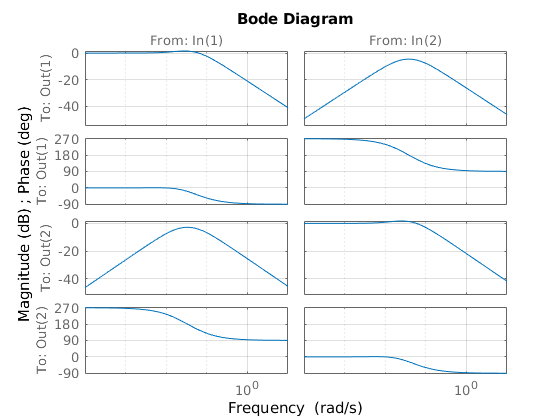

close all; clear; clc;
sys = minphase;
% sys = nonminphase;
[num, denom] = tfdata(sys);
g_11 = tf(num{1,1}, denom{1,1});
g_12 = tf(num{1,2}, denom{1,2});
g_21 = tf(num{2,1}, denom{2,1});
g_22 = tf(num{2,2}, denom{2,2});
G = [g_11, g_12; g_21, g_22];

RGA = evalfr(G,0) .* inv(evalfr(G,0))';

G_tilda = G / evalfr(G, 0); % W_1 = inv(evalfr(G, 0))
bode(G_tilda);
grid on

## Excise 3.1.2

PM = pi / 3;
Wc = 0.1;
% Wc = 0.02;

s = tf('s');
C = Kp + Ki / s;